# Power generation and Energy Budget

## Power Generated with "Sun-Aero" pointing Vs Beta angle at an altitude

### Calculation at one altitude

First, let's see what is the generated power at a certain altitude, with the variation of the beta angle.

To do this, we are simulating an orbit at a fixed date and a constant altitude. Five orbits are simulated and the instantaneous power is calculated and then an average is calculated, to get the mean power generated.

First, the calculation is done for one orbit with a fixed semi-major axis. Notice that the inclination is not important, because at the end, the RAAN is the parameter that really affects the beta angle.

The maximum power generated with the solar array is calculated to be 48W, corresponding to the maximum of 40 cells from the MSP.

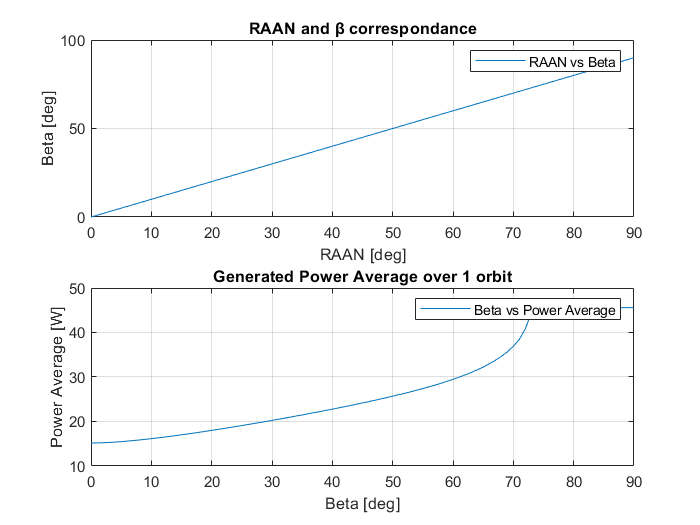

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
orbit.a = 6678e3;     %semimajor axis [m]
orbit.e = 0.001;     %eccentricity
orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

%time step based on gyro sampling frequency: 
TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
N_orbits = 5;           %number of orbits to be simulated
%Time spent performing the simulation in seconds (one orbit is ~5400 s):
t_sim = N_orbits*Torbit;

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;
for i=1:N+1
    orbit.O = (i-1)*paso;
    RAAN(i)= orbit.O ;
    Power=sim('testpropagator');

    time = Power.tout;
    Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
    beta = getdatasamples(Power.beta,(1:length(time)));

    Pav(i)=mean(Pcollected);
    B(i)=mean(beta);
end

figure(1)
set(gcf,'color','w');
    subplot(2,1,1)
        plot(RAAN,B)
        hold on;
        legend('RAAN vs Beta')
        title('RAAN and β correspondance')
        ylabel('Beta [deg]')
        xlabel('RAAN [deg]')
        grid on
    subplot(2,1,2)
        plot(B,Pav)
        hold on;
        legend('Beta vs Power Average')
        title('Generated Power Average over 1 orbit')
        ylabel('Power Average [W]')
        xlabel('Beta [deg]')
        %ylim([0,22])
        grid on

### Calculation at multiple altitudes

The same procedure is done for several orbits with different altitudes. In this case, an efficiency of the power conversion was added, the power conversion efficiency is η=95%

clear
close

%Initialisation of date
date.year=2021;
date.month=3;
date.day=21;
date.hour=12;
date.minutes=0;
date.seconds=0;

%Orbit: Initialisation of Keplerian parameters
%orbit.a = 6678e3;     %semimajor axis [m]

orbit.e = 0.001;     %eccentricity
%orbit.i = 50;     %inclination [degrees]
orbit.O = 0;      %Right ascension of the right ascending node [degrees] %max 197, min 300.5 %181
orbit.o = 0;      %Argument of the perigee [degrees]                      %max 90, min 0      %90
orbit.nu = 0;       %True anomaly [degrees]

eff_Psa=0.95;
Psa=48*eff_Psa;     %this is the maximum power generation

orbit.i=90;
orbit.O=0;
paso=1;
maxRAAN=90;
N=maxRAAN/paso;

for j=1:4
    orbit.a = (6371+200+j*100)*1e3;     %semimajor axis [m]
    %time step based on gyro sampling frequency: 
    TimeStep = 1;        %fixed-step size in solver, Default time step=0.25
    Torbit=2*pi*sqrt((orbit.a/1e3)^3/(3.986004418E5));
    N_orbits = 5;           %number of orbits to be simulated
    %Time spent performing the simulation in seconds (one orbit is ~5400 s):
    t_sim = N_orbits*Torbit;
    for i=1:N+1
        orbit.O = (i-1)*paso;
        RAAN(i)= orbit.O ;
        Power=sim('testpropagator');

        time = Power.tout;
        Pcollected = getdatasamples(Power.Psa1,(1:length(time)));
        beta = getdatasamples(Power.beta,(1:length(time)));

        Pav(j,i)=mean(Pcollected);
        B(j,i)=mean(beta);
    end
end


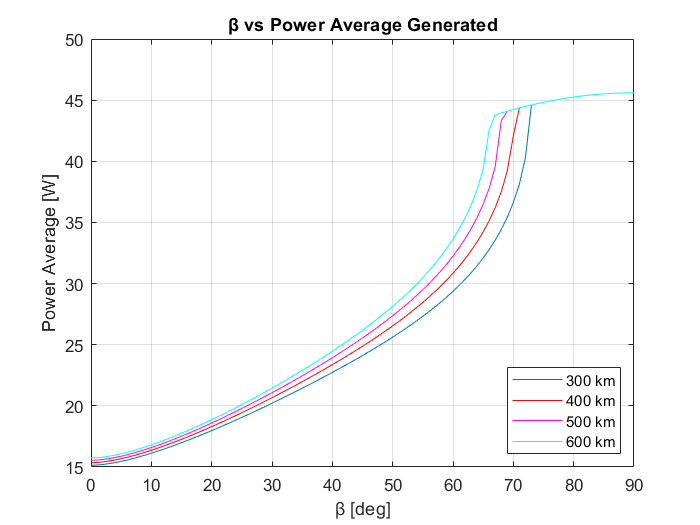

 %load('power_from_beta_and_altitude.mat')   %if we don't want to run the
 %whole simulation again
Pav1=10:0.1:40;
B1 = interp1(Pav(1,:),B(1,:),Pav1);     %Interpolation for altitude 300km
B2 = interp1(Pav(2,:),B(2,:),Pav1);     %Interpolation for altitude 400km, etc
B3 = interp1(Pav(3,:),B(3,:),Pav1);
B4 = interp1(Pav(4,:),B(4,:),Pav1);

figure(2)
set(gcf,'color','w');
        plot(B(1,:),Pav(1,:))
        hold on;
        plot(B(2,:),Pav(2,:),'r')
        plot(B(3,:),Pav(3,:),'m')
        plot(B(4,:),Pav(4,:),'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('β vs Power Average Generated')
        xlabel('β [deg]')
        ylabel('Power Average [W]')
        grid on   

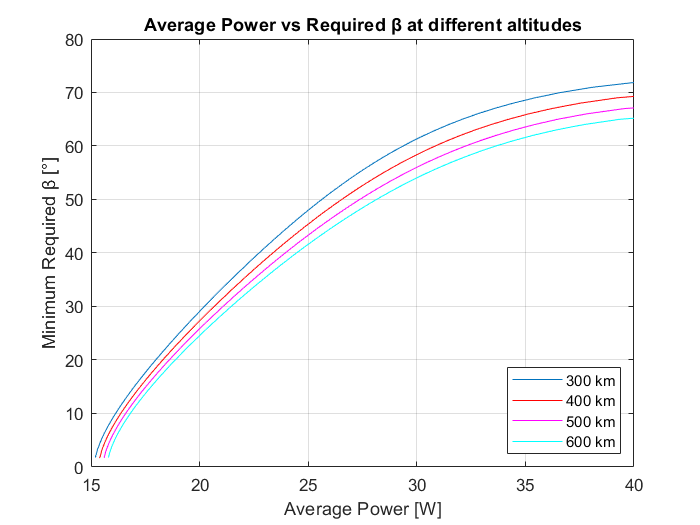

figure(3)
set(gcf,'color','w');
        plot(Pav1,B1)   
        grid on
        hold on;
        plot(Pav1,B2,'r')
        plot(Pav1,B3,'m')
        plot(Pav1,B4,'c')
        legend('300 km','400 km','500 km','600 km')
        legend('Location','southeast')
        title('Average Power vs Required β at different altitudes')
        xlabel('Average Power [W]')
        ylabel('Minimum Required β [°]')
        %ylim([0,22])
        grid on

We can see that the worst case is at the lowest simulated altitude, this is 300km, so, only this case will be further analyzed

The vectors B and Pav are saved as a matrix 'power_from_beta_and_altitude.mat'

        %load('power_from_beta_and_altitude.mat')  

To avoid running this simulation multiple times, only this .mat file is going to be loaded in the next sections.

## Energy balance and Calculation of the duty cycles

Now, the loads will be included to see if the generated power is enough for certain duty cycles.

### Duty cycle of thruster firing vs Duty cycle of thruster power consumption

First, we know that the thruster will be consuming power even before producing a thrust, this is because it needs to heat to the righ temperature before executing a maneuver, the heating time is variable, but for the worst case, it si 16 minutes: $t_{heat}\le16min.$

The actual time that the thruster needs to be producing thrust is the active time, according to the last orbit control, it is fixed to 50 minutes: $t_{thrust}=45min.$

Between two firings, the satellite has some time to recharge its batteries, this is called recharging time and can be in the range from 5.5hs to 12.5hs. $t_{recharge}=[4.166 \ 12.5]hs=[250 \ 750]min=[15 000 \ 45 000] s.$

so, the duty cycle of the thruster, from the point of view of orbit control, i.e., firing, is 


$$Thruster \ Duty \ Cycle = d_{thruster}=\frac {t_{thrust} }{t_{thrust}+t_{heat}+t_{recharge}}$$


However, from the point of view of power consumption, the duty cycle is a bit higher, because the time the thruster will consume power is longer than the time it will be firing:


$$Power \ Thruster \ Duty \ Cycle = d_{power \ thruster}=d=\frac {t_{thrust} + t_{heat} }{t_{thrust}+t_{heat}+t_{recharge}}$$


It is possible to plot the Thruster Power Duty Cycle $d$, as a function of the recharge time in the following plot.

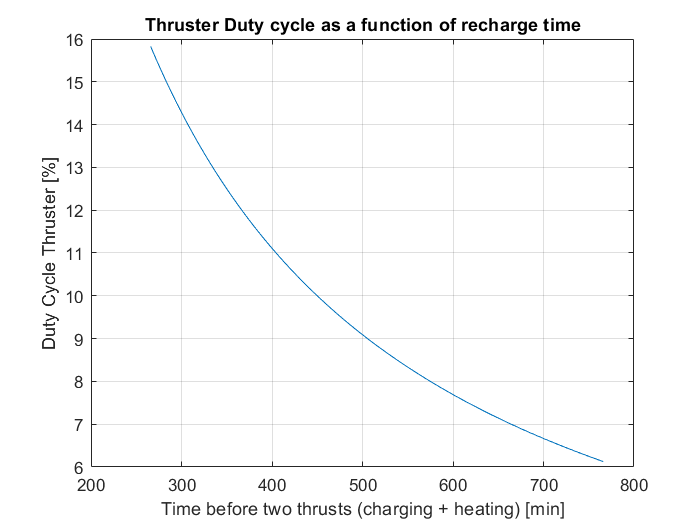

clear all
close all

t_heat=16*60; %heat time in seconds
t_thrust=50*60; %thrust time in seconds
%t_charge=22500:500:45000; %recharge batteries time in seconds
t_charge=15000:50:45000; %recharge batteries time in seconds

duty_cycle_thruster=(t_thrust)./(t_heat+t_thrust+t_charge); %this is the real % of time the thruster will propel the satellite
duty_cycle_power=(t_heat+t_thrust)./(t_heat+t_thrust+t_charge); %because the power consumption is also there when the thruster is heating
%t_charge_calc=t_thrust./duty_cycle_thruster-t_heat-t_thrust;

figure(4)
set(gcf,'color','w');
    plot((t_charge+t_heat)/60,duty_cycle_thruster*100)
    hold on
    grid on
    ylabel('Duty Cycle Thruster [%]')
    xlabel('Time before two thrusts (charging + heating) [min]')
    title('Thruster Duty cycle as a function of recharge time')

It is possible to see that the thruster duty cycle is related with the recharging time in minutes, from the orbit analysis and the drag at different altitudes, the following table shows the required 

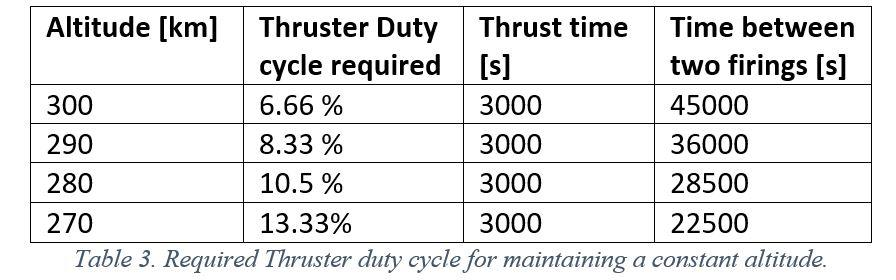

### Duty cycle thruster and thruster power consumption

Assuming that the power consumption of the thruster is 50 W during the thrust and during the heating, while during charge times it only consumes 0.32 W in stand-by mode, and the efficiency of power conversion from the source of power to the thruster is $\eta_{conv}$ is 90%, the average power consumption by cycle would be:


$$Power \ Thruster = P_{thruster}(d)=\frac {50W  \times d + 0.32 W \times (1-d)}{\eta_{conv}}$$


It is possible to plot the consumption of only the thruster, as function of duty cycle (which depends on recharge time).

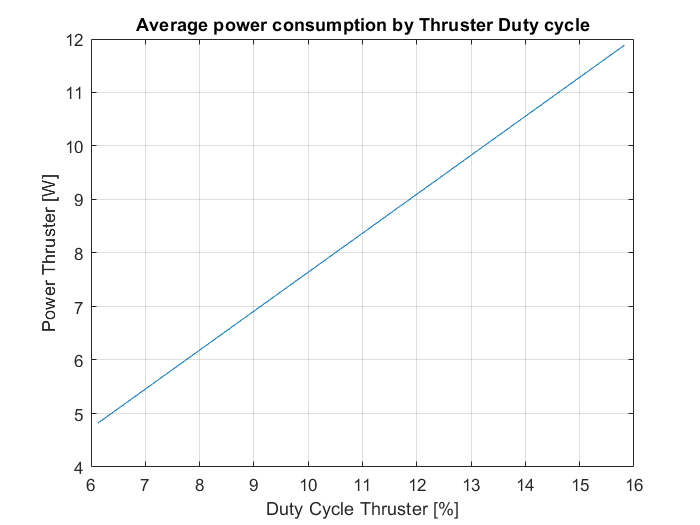

eff_batt2thruster=0.9;  %Battery to thruster efficiency
%the following is the average propulsion power by cycle
P_thruster=(duty_cycle_power*50+(1-duty_cycle_power)*0.32)/eff_batt2thruster;
%P_bus=(P_thruster+0.03*(19.77+4.79)+(1-duty_cycle_power-0.03)*(7.13+4.5))/0.85;

figure(5)
set(gcf,'color','w');
    plot(duty_cycle_thruster*100,P_thruster)
    hold on
    grid on
    xlabel('Duty Cycle Thruster [%]')
    ylabel('Power Thruster [W]')
    title('Average power consumption by Thruster Duty cycle')

### Bus power consumption

In concordance with the updated power budget, which has an average nominal power consumption of 15.84 W (nominal+margin), and during communications (3% duty cycle) of 28.19 W (nominal+margin). The power required by the bus is calculated by the following equation:


$$P_{bus}=P_{thruster}+(1-0.03) \times P_{nominal} + 0.03 \times P_{com}$$


Because $P_{thruster}$ is the average power consumption of the thruster. The satellite will consume communications power (bus+transceivers) $P_{com}$ during 3% of the time and the rest of the time, the platform will be consuming an average nominal power $P_{bus}$ excluding communications.

**NOTE: The values of nominal power consumption and communications power consumption need to be updated with the iterations of the power budget**

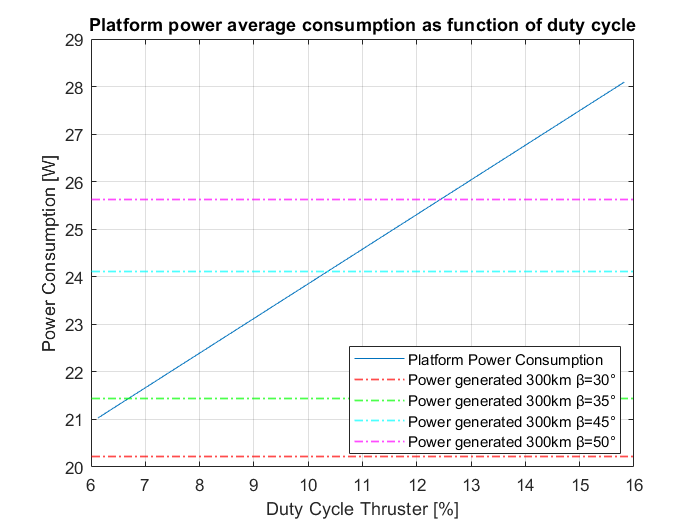

P_nominal=9.82+6.02; %Nominal mode power + Margin [W] FROM POWER BUDGET
P_com=21.15+7.04; %Com mode power + Margin [W]
P_bus=(P_thruster+P_nominal*duty_cycle_power+0.03*P_com+(1-duty_cycle_power-0.03)*P_nominal);
%P_bus=(P_thruster+0.03*P_com+(1-0.03)*P_nominal);

%for the last plot only
load('power_from_beta_and_altitude.mat')
B_Pbus_required = interp1(Pav(1,:),B(1,:),P_bus);     %Interpolation for altitude 300km (worst case)
B30=interp1(B(1,:),Pav(1,:),30); %Power at beta angle = 30 degrees
B35=interp1(B(1,:),Pav(1,:),35); 
B45=interp1(B(1,:),Pav(1,:),45); 
B50=interp1(B(1,:),Pav(1,:),50); 
P22=interp1(Pav(1,:),B(1,:),22); %Beta angle at power = 22 W
P24=interp1(Pav(1,:),B(1,:),24);
P26=interp1(Pav(1,:),B(1,:),26);

figure(6)
set(gcf,'color','w');
    plot(duty_cycle_thruster*100,P_bus)
    hold on
    grid on
    yline(B30, 'r-.','LineWidth',1)
    yline(B35, 'g-.','LineWidth',1)
    yline(B45, 'c-.','LineWidth',1)
    yline(B50, 'm-.','LineWidth',1)
    xlabel('Duty Cycle Thruster [%]')
    ylabel('Power Consumption [W]')
    title('Platform power average consumption as function of duty cycle')
    legend('Platform Power Consumption','Power generated 300km β=30°','Power generated 300km β=35°','Power generated 300km β=45°','Power generated 300km β=50°')
    legend('Location','southeast')

It is evident that when β has a low value, such as β=30°, the power generated is less than the power consumption of all the platform including the average consumption of the thruster with low duty cycles.

### Comparing values of power consumption, duty cycle and β

The results from previous analysis show that the β angle determines the amount of power generation, the larger β, the more power generated.

When β angle is closer to zero, the power generated is less, so to maintain the energy balance, the thruster cannot fire for long periods of time, this is to say that the duty cycle $d$ has to be reduced to very low values. Or in other words, when there is a certain β angle, the thruster cannot be fire at a duty cycle > $d$. This can be seen in the following plots.

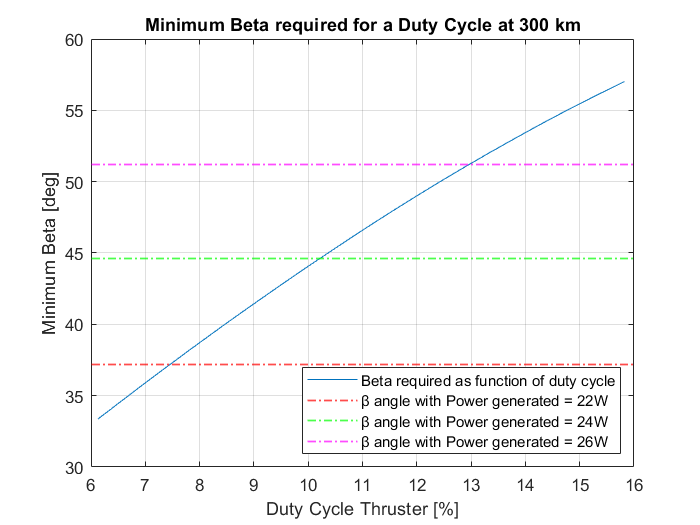

figure(7)
set(gcf,'color','w');
%What I need: from a certain duty cycle: know what is the required BETA
    plot(duty_cycle_thruster*100,B_Pbus_required)
    hold on
    grid on
    yline(P22, 'r-.','LineWidth',1)
    yline(P24, 'g-.','LineWidth',1)
    yline(P26, 'm-.','LineWidth',1)
    xlabel('Duty Cycle Thruster [%]')
    ylabel('Minimum Beta [deg]')
    title('Minimum Beta required for a Duty Cycle at 300 km')
    legend('Beta required as function of duty cycle','β angle with Power generated = 22W','β angle with Power generated = 24W','β angle with Power generated = 26W' )
    legend('Location','southeast')

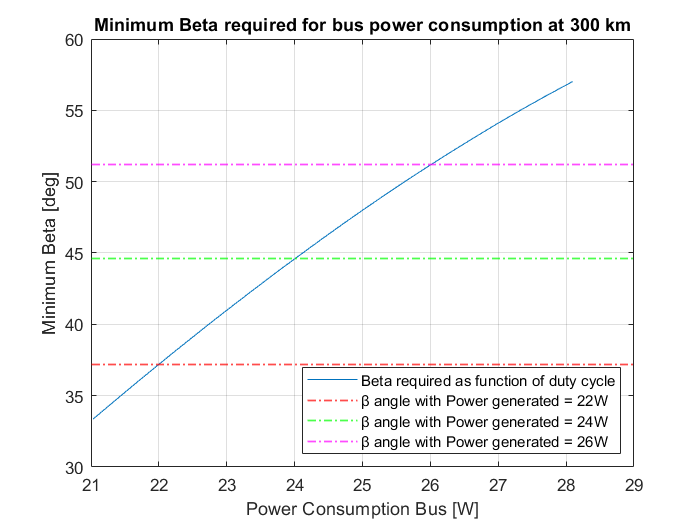


%From a certain power consumption: know what is the required BETA
figure(8)
set(gcf,'color','w');
    plot(P_bus,B_Pbus_required)
    hold on
    grid on
    yline(P22, 'r-.','LineWidth',1)
    yline(P24, 'g-.','LineWidth',1)
    yline(P26, 'm-.','LineWidth',1)
    xlabel('Power Consumption Bus [W]')
    ylabel('Minimum β [deg]')
    title('Minimum β required for bus power consumption at 300 km')
    legend('β required as function of duty cycle','β angle with Power generated = 22W','β angle with Power generated = 24W','β angle with Power generated = 26W' )
    legend('Location','southeast')

### Maximum duty cycle *d_thruster* as function of β

OK, now the objective is to find $d_{thruster}=f(\beta)$

To do so, first it is known that:

$P_{generated}=f(\beta)$, for values of β from 0 to 90 degrees, there is an amount of average power generated for β=0 the power generated is 15.14W, and for β=90 the power generated is 45.6W

Also, the power consumption of the satellite bus is:

$P_{bus}=f(d_{thruster})=f(g(t_{recharge}))$, which means that the duty cycle of the impulse produced by the thruster, this duty cycle of thruster also depends on the time to recharge the batteries. So, a range of recharge times has to be selected, so there will be a range of values for duty cycle; the values of recharge times selected was from 3 500 seconds (highest duty cycle) to 120 000 seconds (lowest duty cycle)

From there, there will be an interpolation of the values, knowing that:

$P_{bus} \le P_{generated}$, at the limit, when the generated power is the consumed power, we get the maximum duty cycle that can be used.

As we know that the genreated power depends on β, we can get the values of power consumption and extrapolate to the maximum duty cycle depending on β.

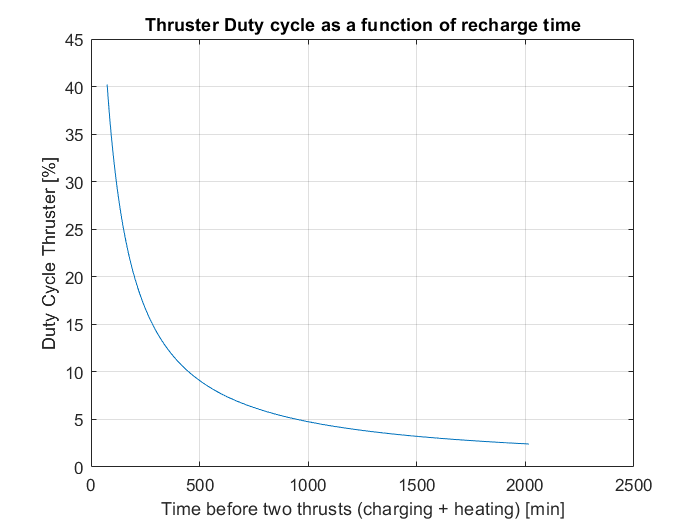

clear all
close all
t_heat=16*60; %heat time in seconds
t_thrust=50*60; %thrust time in seconds
t_charge=3500:50:120000; %recharge batteries time in seconds

duty_cycle_thruster=(t_thrust)./(t_heat+t_thrust+t_charge); %this is the real % of time the thruster will propel the satellite
duty_cycle_power=(t_heat+t_thrust)./(t_heat+t_thrust+t_charge); %because the power consumption is also there when the thruster is heating

figure(9)
set(gcf,'color','w');
    plot((t_charge+t_heat)/60,duty_cycle_thruster*100)
    hold on
    grid on
    ylabel('Duty Cycle Thruster [%]')
    xlabel('Time before two thrusts (charging + heating) [min]')
    title('Thruster Duty cycle as a function of recharge time')

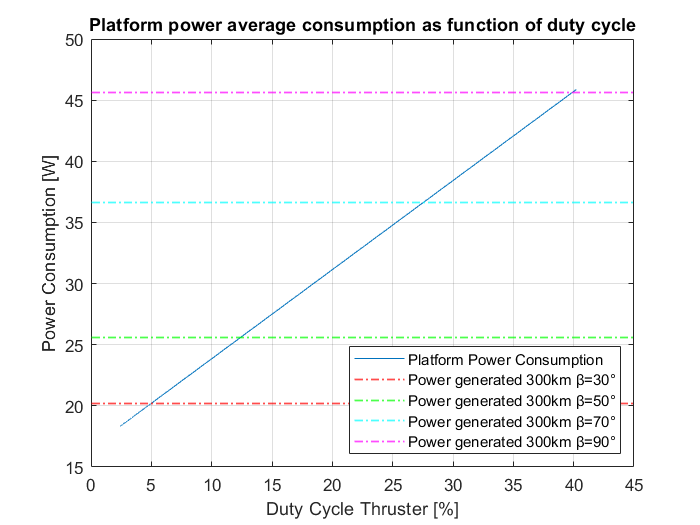

    
eff_batt2thruster=0.9;  %Battery to thruster efficiency
%the following is the average propulsion power by cycle
P_thruster=(duty_cycle_power*50+(1-duty_cycle_power)*0.32)/eff_batt2thruster;
P_nominal=9.82+6.02; %Nominal mode power + Margin [W] FROM POWER BUDGET
P_com=21.15+7.04; %Com mode power + Margin [W]
P_bus=(P_thruster+P_nominal*duty_cycle_power+0.03*P_com+(1-duty_cycle_power-0.03)*P_nominal);

load('power_from_beta_and_altitude.mat')
%for the top plot only
B_Pbus_required = interp1(Pav(1,:),B(1,:),P_bus);     %Interpolation for altitude 300km (worst case)
B30=interp1(B(1,:),Pav(1,:),30); %Power at beta angle = 30 degrees
B50=interp1(B(1,:),Pav(1,:),50); 
B70=interp1(B(1,:),Pav(1,:),70); 
B90=interp1(B(1,:),Pav(1,:),90); 

figure(10)
set(gcf,'color','w');
    plot(duty_cycle_thruster*100,P_bus)
    hold on
    grid on
    yline(B30, 'r-.','LineWidth',1)
    yline(B50, 'g-.','LineWidth',1)
    yline(B70, 'c-.','LineWidth',1)
    yline(B90, 'm-.','LineWidth',1)
    xlabel('Duty Cycle Thruster [%]')
    ylabel('Power Consumption [W]')
    title('Platform power average consumption as function of duty cycle')
    legend('Platform Power Consumption','Power generated 300km β=30°','Power generated 300km β=50°','Power generated 300km β=70°','Power generated 300km β=90°')
    legend('Location','southeast')

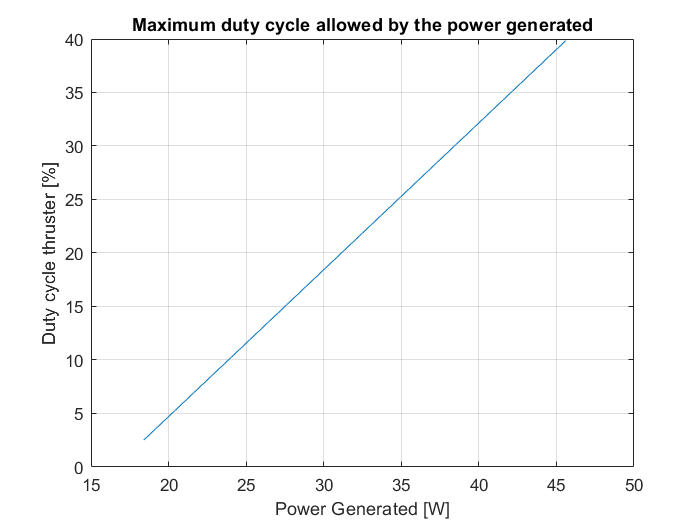

%Pbus= 1:1:30;
Pgen=Pav(1,:);          %this is the power generated at 300km as a function of beta
Betafull=B(1,:);        %this is the full range of beta, from 0 to 90 degrees
d_pbus=interp1(P_bus,duty_cycle_thruster*100,Pgen);     %this interpolates and gets the duty cycle

figure(11)
set(gcf,'color','w');
plot(Pgen,d_pbus)
    hold on
    grid on
    xlabel('Power Generated [W]')
    ylabel('Duty cycle thruster [%]')
    title('Maximum duty cycle allowed by the power generated')

figure(12)
set(gcf,'color','w');
plot(Betafull,d_pbus)
    hold on
    grid on
    xlabel('β angle [deg]')
    ylabel('Duty cycle thruster [%]')
    title('Maximum duty cycle allowed by the β angle')

This function is going to be implemented in the orbit control simulations, the beta angle will be measured, and according to this angle, the duty cycle will be adjusted to its maximum value.

This function in GMAT is descibed with the following expression:

Which gives very similar results as the more precise extrapolation, the following plot shows this.

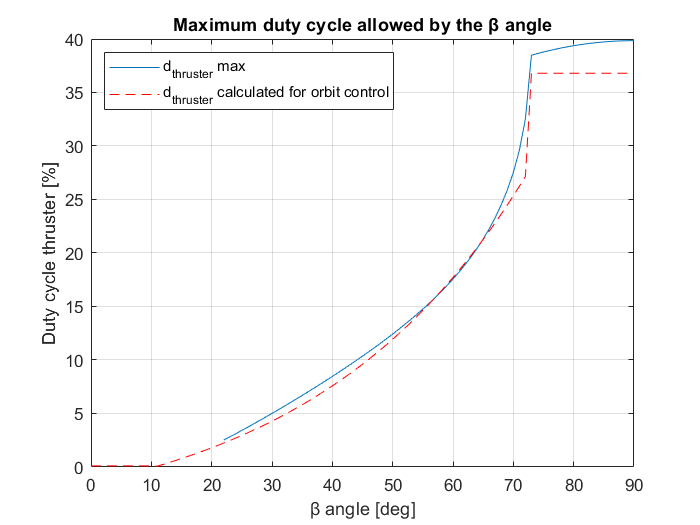

absBetaAngle=0:1:90;
for i=1:length(absBetaAngle)
    powergenerated(i) = 12 + 3.4* exp( absBetaAngle(i)/35.7);
    if absBetaAngle(i)>72
        powergenerated(i)=45;
    end
end

dutyTime = ( powergenerated - 16.566)/77.28;
    dutyTime(dutyTime<=0)=0.001;

figure(12)
plot(absBetaAngle,dutyTime*100,'r--')
legend('d_{thruster} max','d_{thruster} calculated for orbit control')
legend('Location','northwest')

## Available power and duty cycle from an ISS inclination orbit

Now, let's see what happens from an orbit like the ISS orbit.

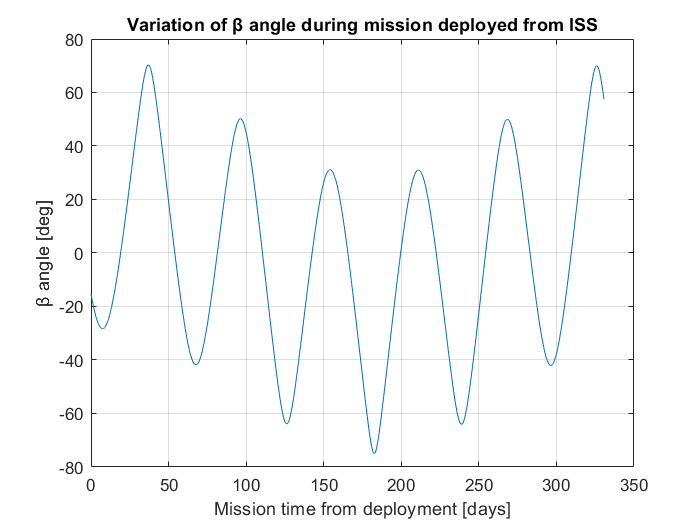

close all 
% clear all
load('power_from_beta_and_altitude.mat')
B_Pbus_required = interp1(Pav(1,:),B(1,:),P_bus);     %Interpolation for altitude 300km (worst case)
load('ISS_GMAT.mat')
P_ISS=interp1(B(1,:),Pav(1,:),abs(bISS)); 
%the duty cycle cannot be more than duty_max, otherwise, not enough power
duty_max=interp1(B_Pbus_required,duty_cycle_thruster*100,abs(bISS));
t_charge_max=(((t_thrust)./(duty_max/100))-(t_heat+t_thrust))/60;
%duty_cycle_thruster=((t_thrust)./(t_heat+t_thrust+t_charge))/60; %this is the real % of time the thruster will propel the satellite

figure(13)
set(gcf,'color','w');
    plot(daysISS,bISS)
    hold on
    grid on
    title('Variation of β angle during mission deployed from ISS')
    xlabel('Mission time from deployment [days]')
    ylabel('β angle [deg]')

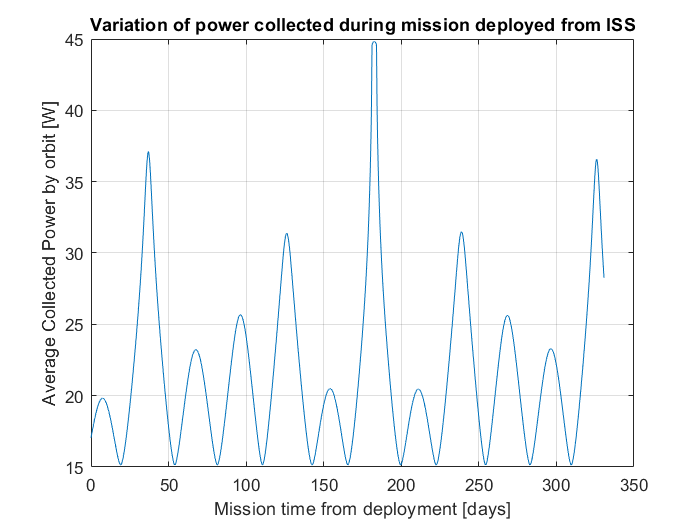

%yyaxis right
figure(14)
set(gcf,'color','w');
    plot(daysISS,P_ISS)
    grid on
    title('Variation of power collected during mission deployed from ISS')
    xlabel('Mission time from deployment [days]')
    ylabel('Average Collected Power by orbit [W]')

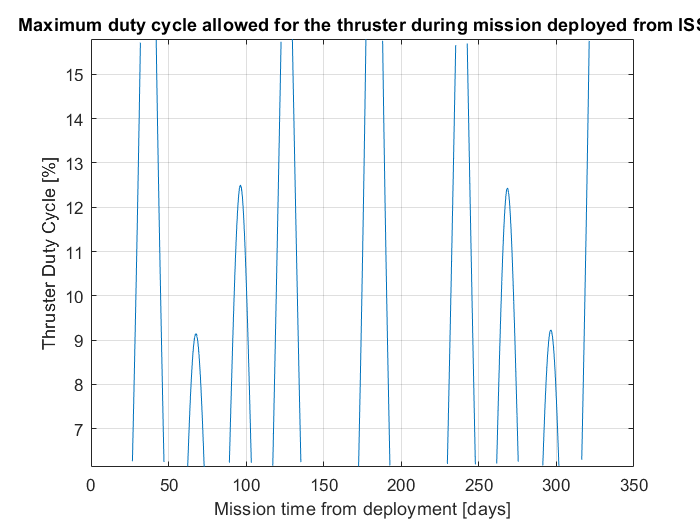

figure(15)
set(gcf,'color','w');
    plot(daysISS,duty_max)
    ylim([min(duty_max) max(duty_max)])
    xlabel('Mission time from deployment [days]')
    ylabel('Thruster Duty Cycle [%]')
    grid on
    title('Maximum duty cycle allowed for the thruster during mission deployed from ISS')

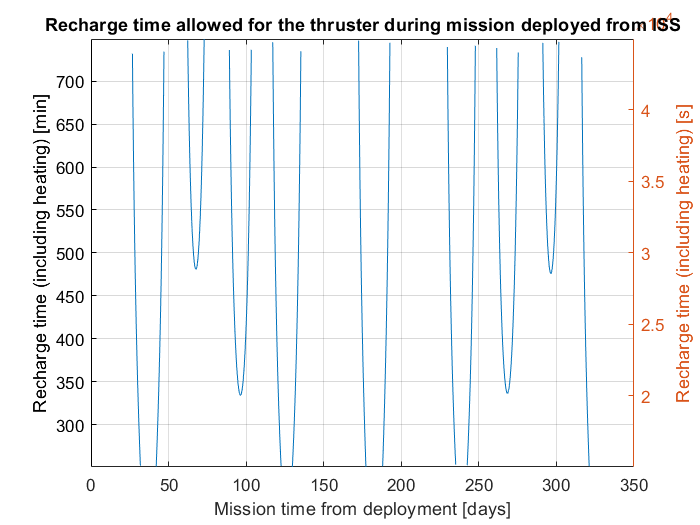

figure(16)
set(gcf,'color','w');
    plot(daysISS,t_charge_max)
    ylim([min(t_charge_max) max(t_charge_max)])
    grid on
    xlabel('Mission time from deployment [days]')
    ylabel('Recharge time (including heating) [min]')
    yyaxis right
    ylim([min(t_charge_max)*60 max(t_charge_max)*60])
    title('Recharge time allowed for the thruster during mission deployed from ISS')
    ylabel('Recharge time (including heating) [s]')

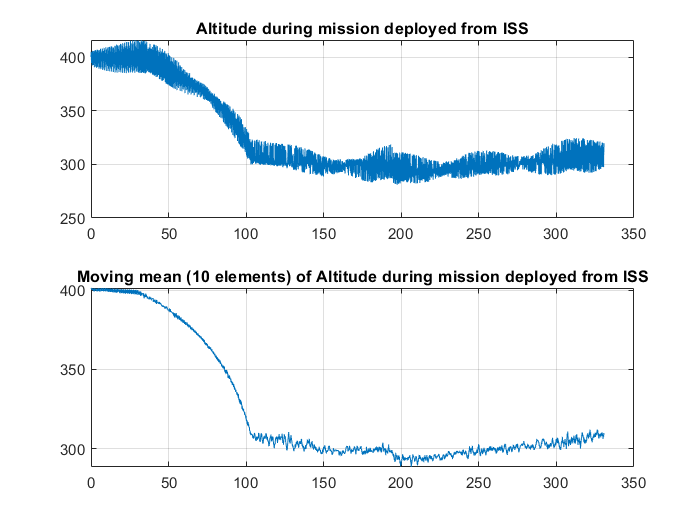

figure(17)
set(gcf,'color','w');
subplot(2,1,1)
    plot(daysISS,altISS)
    hold on
    grid on
    title('Altitude during mission deployed from ISS')
%yyaxis right
subplot(2,1,2)
    plot(daysISS,movmean(altISS,10))
    grid on
    title('Moving mean (10 elements) of Altitude during mission deployed from ISS')

## Available power and duty cycle from a SSO

Same for a SSO orbit

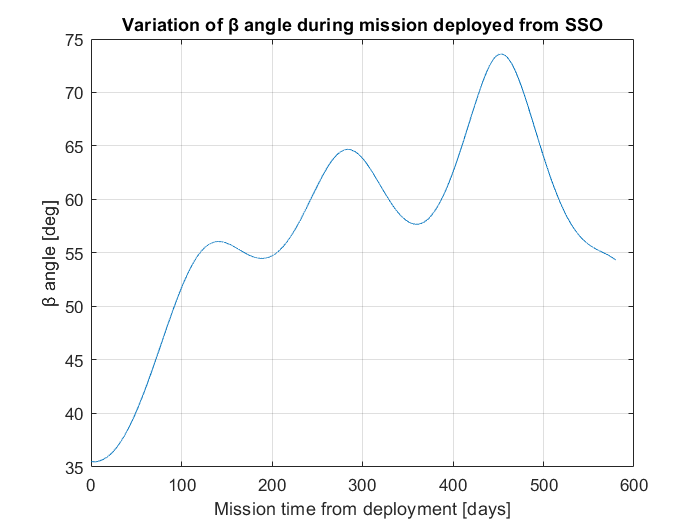

close all
load('power_from_beta_and_altitude.mat')
load('SSO_GMAT.mat')
P_SSO=interp1(B(1,:),Pav(1,:),abs(bSSO)); 
%the duty cycle cannot be more than duty_max, otherwise, not enough power
duty_max=interp1(B_Pbus_required,duty_cycle_thruster*100,abs(bSSO));
t_charge_max=(((t_thrust)./(duty_max/100))-(t_heat+t_thrust))/60;
%duty_cycle_thruster=((t_thrust)./(t_heat+t_thrust+t_charge))/60; %this is the real % of time the thruster will propel the satellite

figure(18)
set(gcf,'color','w');
    plot(daysSSO,bSSO)
    hold on
    grid on
    title('Variation of β angle during mission deployed from SSO')
    xlabel('Mission time from deployment [days]')
    ylabel('β angle [deg]')

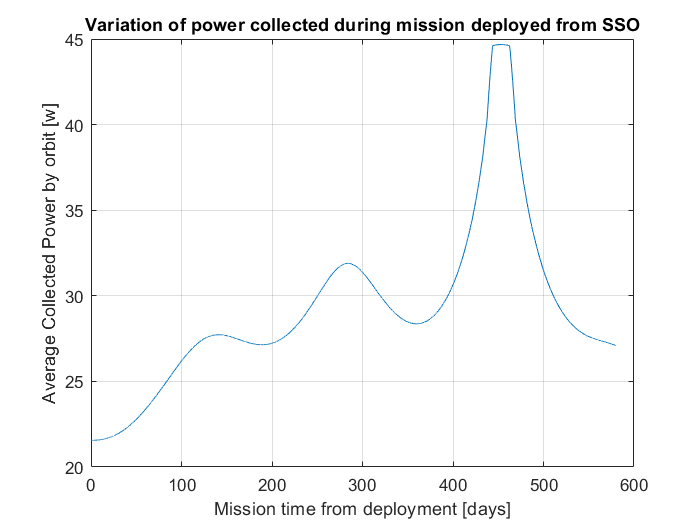

%yyaxis right
figure(19)
set(gcf,'color','w');
    plot(daysSSO,P_SSO)
    grid on
    title('Variation of power collected during mission deployed from SSO')
    xlabel('Mission time from deployment [days]')
    ylabel('Average Collected Power by orbit [w]')

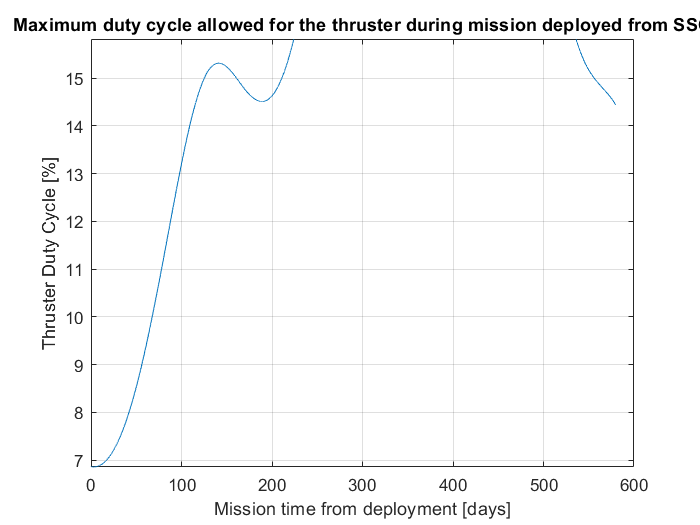

figure(20)
set(gcf,'color','w');
    plot(daysSSO,duty_max)
    ylim([min(duty_max) max(duty_max)])
    xlabel('Mission time from deployment [days]')
    ylabel('Thruster Duty Cycle [%]')
    grid on
    title('Maximum duty cycle allowed for the thruster during mission deployed from SSO')

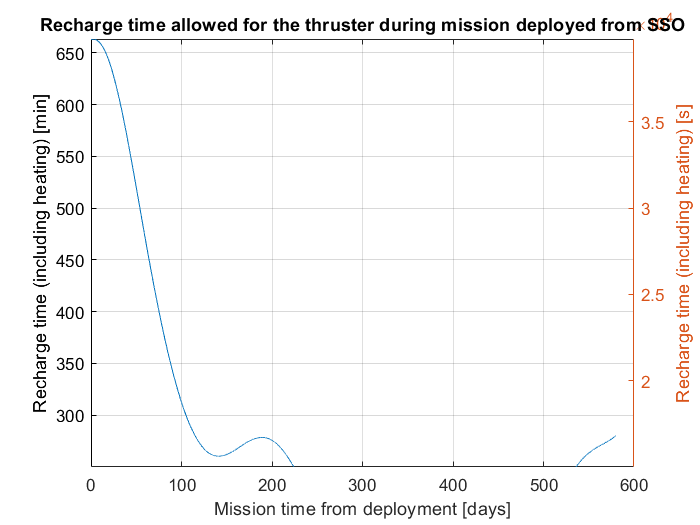

figure(21)
set(gcf,'color','w');
    plot(daysSSO,t_charge_max)
    ylim([min(t_charge_max) max(t_charge_max)])
    grid on
    xlabel('Mission time from deployment [days]')
    ylabel('Recharge time (including heating) [min]')
    yyaxis right
    ylim([min(t_charge_max)*60 max(t_charge_max)*60])
    title('Recharge time allowed for the thruster during mission deployed from SSO')
    ylabel('Recharge time (including heating) [s]')